# Demonstration of DE Analysis and Marker Gene Identification Functions in scGEAToolbox

## Load example data set, X

cdgea; % set working directory
load example_data/markergeneident_demo X genelist s_tsne

## Group cells into clusters (k=6)

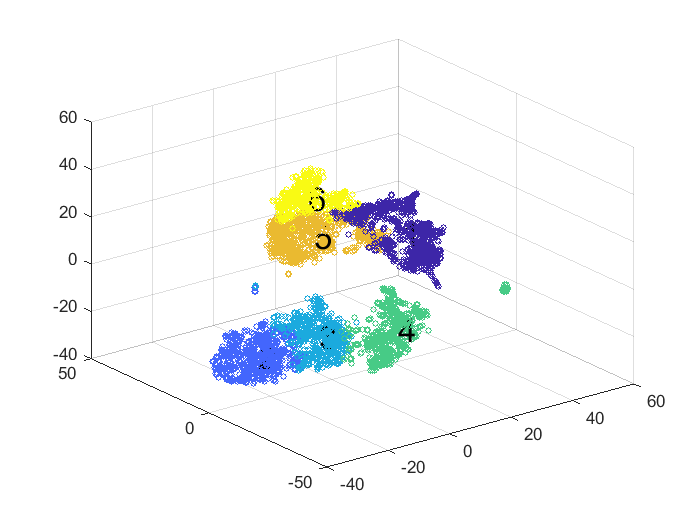

figure;
rng(1234)
cluster_kmedoids=sc_clustshow(s_tsne,6,'type','kmedoids');

## Identify marker genes for cluster 4

markers_genelist=sc_pickmarkers(X,genelist,cluster_kmedoids,4);

## Plot top 9 marker genes' expression among cells

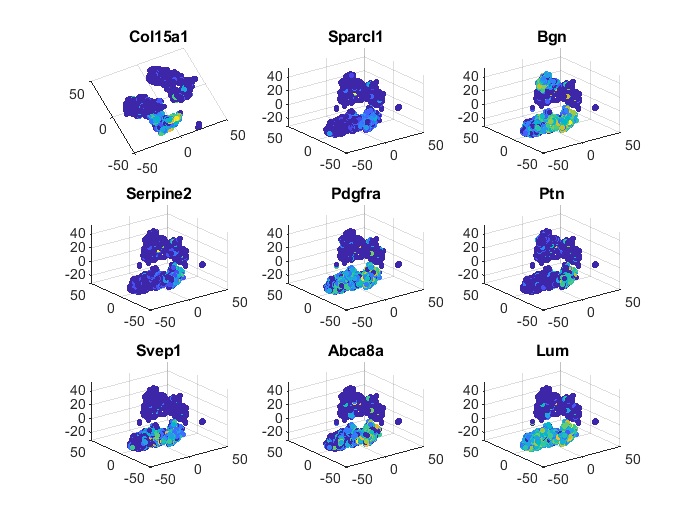

figure;
for k=1:9
    g=markers_genelist(k);
    subplot(3,3,k)
    scatter3(s_tsne(:,1),s_tsne(:,2), s_tsne(:,3), 10,...
    log(1+X(genelist==g,:)), 'filled');
    title(g)
end


subplot(3,3,1)
view([-25 90])

## Plot the top marker gene's expression among cells

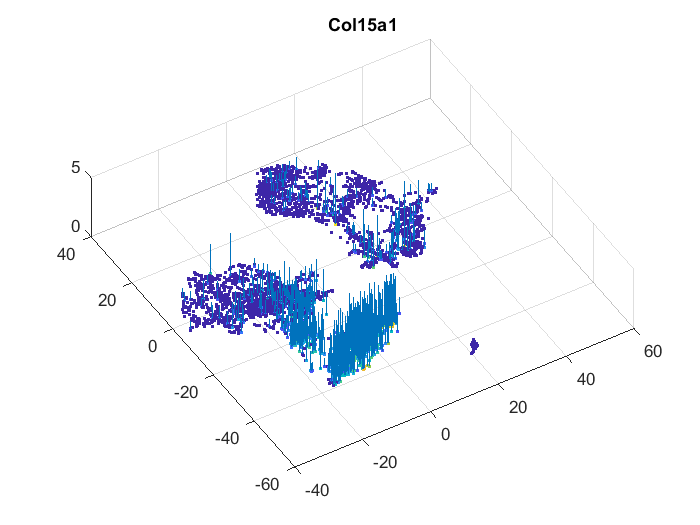

figure;
g=markers_genelist(1);
sc_stemscatter(s_tsne(:,1), s_tsne(:,2), log(1+X(genelist==g,:)));
title(g)

view([-31.03 77.60])

## The End